# Esercizi vari sulla propagazione dell'incertezza 

## Determinazione della pdf dell'errore in ingresso, e calcolo di WCU, SU, EU

Acronimi:

- WCU = worst-case uncertainty = incertezza di caso peggiore

- SU = standard uncertainty = incertezza standard (anche "incertezza tipo")

- EU = expanded uncertainty = incertezza estesa

% Per ogni caso si vuole conoscere WCU, SU, EU, e la pdf dell'errore in ingresso.
% U1 si riferisce al caso 1, u2 al caso 2, ecc.

% Dati
U1 = 1 % WCU; non sappiamo altro

U1 = 1

u2 = 1 % SU; non sappiamo altro

u2 = 1

Ucp3 = 1 % EU; non sappiamo altro

Ucp3 = 1

U4 = 1 % WCU; la distribuzione è triangolare

U4 = 1

U5 = 1 % WCU; la distribuzione è arcoseno

U5 = 1

U6 = 1 % WCU; la distribuzione è a campana, convoluzione di tre distribuzioni uniformi identiche

U6 = 1


Nsim = 1e6; % numero di campioni di errore da generare
cp = 0.95 % probabilità di copertura

cp = 0.9500


% Domande
% kcp % fattore di copertura associato a cp
% U1, u1, Ucp1; U2, u2, Ucp2; ecc. = WCU, SU, EU per ogni caso
% e1, e2, ecc. = vettore riga di Nsim errori, distribuiti secondo la pdf appropriata, per ogni caso
% Ucp1_sim, Ucp2_sim, ecc. = Ucp calcolata in base alla popolazione di Nsim errori e1, e2, ecc.
% Tracciare un istogramma pdf degli errori, con indicate u, Ucp, U, per ogni caso

% Nota: ove appropriato, per calcolare Ucp si usi l'approssimazione gaussiana

### Soluzione

kcp = norminv((1+cp)/2) % fattore di copertura di tipo B

kcp = 1.9600

1) Nota la sola WCU = *pdf rettangolare*

U1 = U1 % dato

U1 = 1

u1 = U1/sqrt(3) % pdf rettangolare

u1 = 0.5774

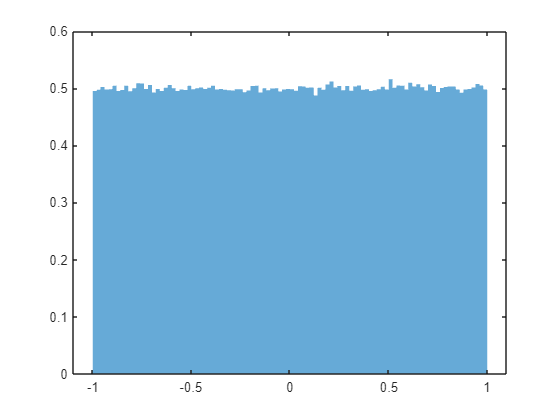

e1 = unifrnd(-U1,U1,[1,Nsim]);
histogram(e1,'Normalization','pdf','EdgeColor','none')

*Per pdf non a campana, la EU (che normalmente ha cp >= 90%) può essere approssimata con la WCU*

% Per pdf non a campana, la EU (che normalmente ha cp >= 90%) può essere approssimata con la WCU
Ucp1 = U1 % UE approssimata

Ucp1 = 1

% Formule esatte (che mi interessano poco in questo caso)
Ucp1 = U1*cp % UE esatta

Ucp1 = 0.9500

Ucp1 = unifinv((1+cp)/2,-U1,U1) % UE esatta, applicando la formula generale (cumulativa inversa)

Ucp1 = 0.9500

Ucp1_sim = quantile(e1, (1+cp)/2) % UE calcolata con gli errori simulati

Ucp1_sim = 0.9503

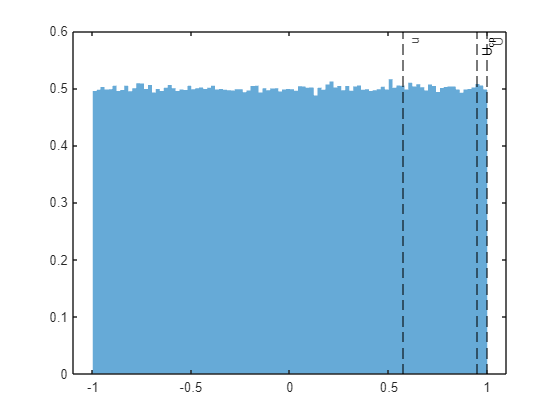

histogram(e1,'Normalization','pdf','EdgeColor','none')
xline(u1,'--k','u')
xline(Ucp1,'--k','U_{cp}')
xline(U1,'--k','U')

2) Nota la sola SU = *pdf gaussiana*

u2 = u2 % dato

u2 = 1

U2 = inf % pdf gaussiana

U2 = Inf

Ucp2 = kcp*u2 % pdf gaussiana -> EU = fattore di copertura x SU

Ucp2 = 1.9600

% e2 = normrnd(0,u2,[1,Nsim]);
e2 = randn([1,Nsim])*u2; % equivalente

Ucp2_sim = quantile(e2, (1+cp)/2)

Ucp2_sim = 1.9561

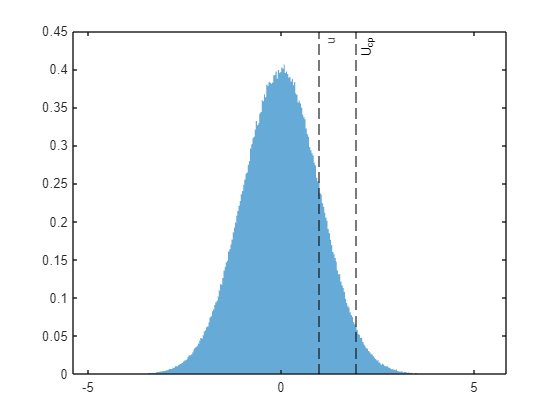

histogram(e2,'Normalization','pdf','EdgeColor','none')
xline(u2,'--k','u')
xline(Ucp2,'--k','U_{cp}')
xline(U2,'--k','U')

3) Nota la sola EU = *pdf gaussiana*

Ucp3 = Ucp3 % dato

Ucp3 = 1

u3 = Ucp3/kcp % formula per pdf gaussiana

u3 = 0.5102

U3 = inf % pdf gaussiana

U3 = Inf

% e3 = normrnd(0,u3,[1,Nsim]);
e3 = randn([1,Nsim])*u3;
Ucp3_sim = quantile(e3, (1+cp)/2)

Ucp3_sim = 1.0008

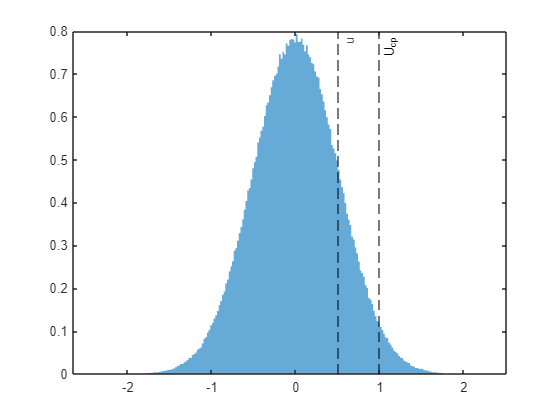

histogram(e3,'Normalization','pdf','EdgeColor','none')
xline(u3,'--k','u')
xline(Ucp3,'--k','U_{cp}')
xline(U3,'--k','U')

4) Pdf triangolare con WCU = U    =     *l'errore è somma di due errori indipendenti a pdf uniforme con WCU = U/2*

U4 = U4 % dato

U4 = 1

u4 = U4/sqrt(3*2) % pdf triangolare

u4 = 0.4082

Ucp4 = kcp*u4 % approssimazione gaussiana

Ucp4 = 0.8002

U0 = U4/2; % WCU di ciascuno dei due errori
e4a = unifrnd(-U0,U0,[1,Nsim]); % prima componente di e4
e4b = unifrnd(-U0,U0,[1,Nsim]); % seconda componente di e4
e4 =  e4a + e4b;

Ucp4_sim = quantile(e4, (1+cp)/2)

Ucp4_sim = 0.7759

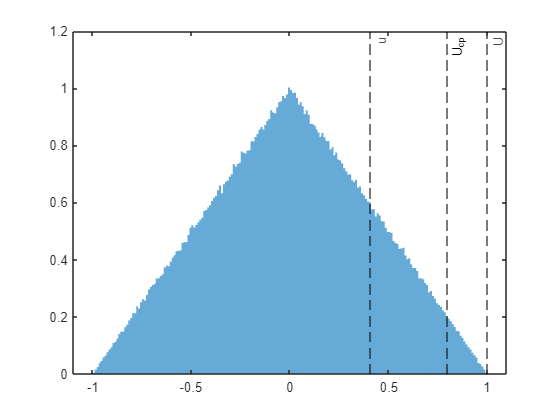

histogram(e4,'Normalization','pdf','EdgeColor','none')
xline(u4,'--k','u')
xline(Ucp4,'--k','U_{cp}')
xline(U4,'--k','U')

5) Pdf arcoseno = *pdf di un errore che nel dominio del tempo segue un andamento sinusoidale*

U5 = U5 % dato

U5 = 1

u5 = U5/sqrt(2) % SU

u5 = 0.7071

% Per pdf non a campana, la EU (che normalmente ha cp >= 90%) può essere approssimata con la WCU
Ucp5 = U5 % EU approssimata

Ucp5 = 1

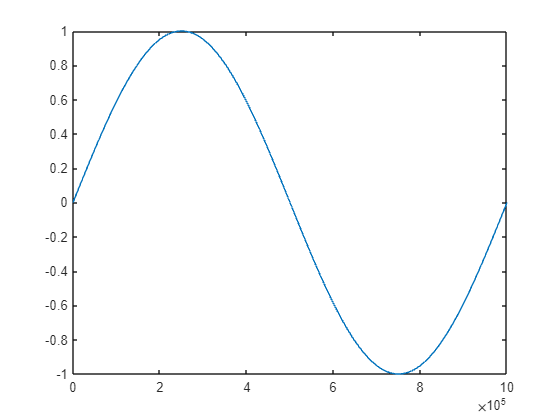

n = [0:Nsim];
Np = 1;
W = 2*pi*Np/Nsim;
e5 = U5*sin(W*n);
plot(n,e5) % andamento dell'errore nel dominio del tempo

Ucp5_sim = quantile(e5, (1+cp)/2)

Ucp5_sim = 0.9969

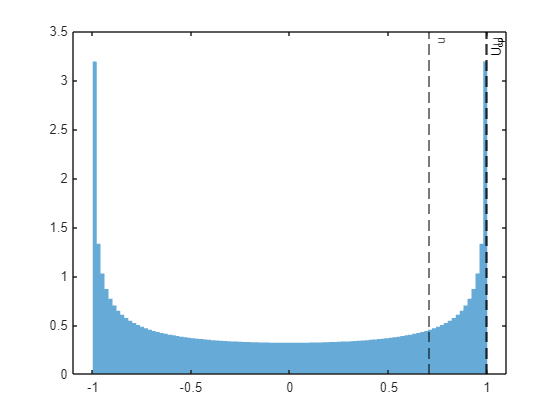

histogram(e5,'Normalization','pdf','EdgeColor','none')
xline(u5,'--k','u')
xline(Ucp5_sim,'--k','U_{cp}')
xline(U5,'--k','U')

6) Pdf convoluzione di tre distribuzioni uniformi identiche

U6 = U6 % dato

U6 = 1

u6 = U6/sqrt(3*3)

u6 = 0.3333

Ucp6 = kcp*u6 % approx gaussiana

Ucp6 = 0.6533

U0 = U6/3

U0 = 0.3333

e6a = unifrnd(-U0,U0,[1,Nsim]); % prima componente di e4
e6b = unifrnd(-U0,U0,[1,Nsim]); % seconda componente di e4
e6c = unifrnd(-U0,U0,[1,Nsim]); % terza componente di e4
e6 =  e6a + e6b + e6c;

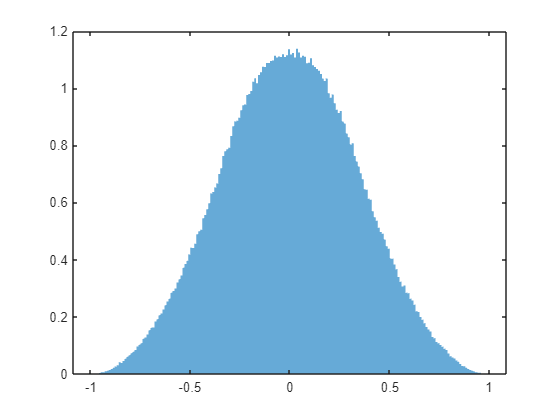

histogram(e6,'Normalization','pdf','EdgeColor','none')

Ucp6_sim = quantile(e6,(1+cp)/2)

Ucp6_sim = 0.6453

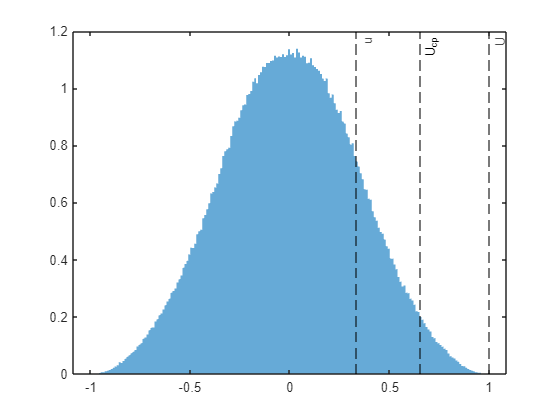

histogram(e6,'Normalization','pdf','EdgeColor','none')
xline(u6,'--k','u')
xline(Ucp6,'--k','U_{cp}')
xline(U6,'--k','U')

## Misure mediante triangolazione (coefficienti di sensibilità assoluti)

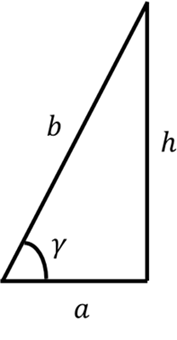

Grandezze in ingresso e in uscita:

- x = [a; gamma] % vettore grandezze in ingresso

- theta = [h; b] % vettore in uscita grandezze in uscita

Modello della misurazione (da calcolare a mano durante l'esame):

- h = a*tan(gamma)

- b = a/cos(gamma)

### Calcolo simbolico della matrice C (consiglio: da fare a mano all'esame)

clear
syms a gamma real
x = [a;gamma] % variabili di ingresso

$$x = \left(\begin{array}{c} a\\ \gamma \end{array}\right)$$

h = a*tan(gamma); % altezza
b = a/cos(gamma); % distanza dalla sommità
theta = [h;b] % variabili di uscita

$$theta = \left(\begin{array}{c} a\,\tan\left(\gamma \right)\\ \frac{a}{\cos\left(\gamma \right)} \end{array}\right)$$

C = jacobian(theta,x) % matrice jacobiana

$$C = \left(\begin{array}{cc} \tan\left(\gamma \right) & a\,\left({\tan\left(\gamma \right)}^{2}+1\right)\\ \frac{1}{\cos\left(\gamma \right)} & \frac{a\,\sin\left(\gamma \right)}{{\cos\left(\gamma \right)}^{2}} \end{array}\right)$$

### Quesito (il vero quesito da esame)

% Si calcolino le grandezze in uscita e le loro incertezze, in base ai dati sulle grandezze in ingresso. 
% Gli errori in ingresso sono indipendenti.
%
% Convenzione:
% x = [a; gamma] % vettore grandezze in ingresso
% theta = [h; b] % vettore grandezze in uscita

% Dati
clear

a = 10

a = 10

gamma_deg = 75 % angolo in gradi

gamma_deg = 75


Ur_a = 0.01 % incertezza relativa

Ur_a = 0.0100

U_gamma_deg = 0.1 % incertezza assoluta in gradi

U_gamma_deg = 0.1000


cp = 0.95

cp = 0.9500


% Domande
% h
% b
% U % vettore WCU in ingresso
% u % vettore SU in ingresso
% C % matrice coefficienti di sensibilità
% U_theta % vettore WCU in uscita 
% u_theta % vettore SU in uscita
% R_theta % matrice coefficienti di correlazione in uscita
% rho_theta_12 % coefficiente di correlazione tra gli errori in uscita sulle grandezze theta(1) e theta(2)
% kmax % massimo fattore di copertura applicabile 
% kcp % fattore di copertura per la probabilità di copertura cp
% Ucp_theta % vettore incertezze estese in uscita con probabilità di copertura cp

### Soluzione

gamma = gamma_deg/180*pi % da gradi a radianti

gamma = 1.3090

h = a*tan(gamma)

h = 37.3205

b = a/cos(gamma)

b = 38.6370

U_a = Ur_a*abs(a) % WCU su a

U_a = 0.1000

U_gamma = U_gamma_deg/180*pi % WCU su gamma

U_gamma = 0.0017

U = [U_a; U_gamma] % vettore WCU

U =     0.1000
    0.0017


u = U/sqrt(3) % vettore SU

u =     0.0577
    0.0010


C = [tan(gamma), a*(tan(gamma)^2 + 1); 1/cos(gamma), a*sin(gamma)/cos(gamma)^2] % matrice C

C =     3.7321  149.2820
    3.8637  144.1954


U_theta = abs(C)*U % WCU in uscita

U_theta =     0.6338
    0.6380


Sigma = diag(u)^2 % matrice covarianza in ingresso

Sigma =     0.0033         0
         0    0.0000


Sigma_theta = C*Sigma*C' % propagazione incertezza standard

Sigma_theta =     0.0691    0.0699
    0.0699    0.0709


u_theta = sqrt(diag(Sigma_theta))

u_theta =     0.2628
    0.2662


R_theta = diag(u_theta)^-1*Sigma_theta*diag(u_theta)^-1

R_theta =     1.0000    0.9995
    0.9995    1.0000


rho_theta_12 = R_theta(1,2)

rho_theta_12 = 0.9995

kmax = U_theta./u_theta

kmax =     2.4117
    2.3967


kcp = norminv((1+cp)/2)

kcp = 1.9600

Ucp_theta = kcp*u_theta

Ucp_theta =     0.5150
    0.5218


### Verifica con metodo Monte Carlo (non richiesta all'esame)

Nsim = 1e6; % numero di simulazioni

e_a = unifrnd(-U_a,U_a,[1,Nsim]); % Nsim errori su a
e_gamma = unifrnd(-U_gamma,U_gamma,[1,Nsim]); % Nsim errori su gamma

a_MC = a + e_a; % Nsim misure di a
gamma_MC = gamma + e_gamma; % Nsim misure di gamma

h_MC = a_MC.*tan(gamma_MC); % Nsim misure di h
b_MC = a_MC./cos(gamma_MC); % Nsim misure di b

e_h = h_MC - h; % Nsim errori di misura su h
e_b = b_MC - b; % Nsim errori di misura su b

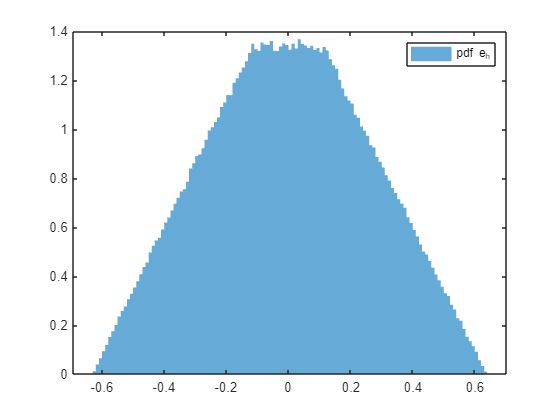

histogram(e_h,'Normalization','pdf','EdgeColor','none')
legend('pdf e_h')

U_h = max(abs(e_h)) % WCU calcolata dagli Nsim errori

U_h = 0.6366

u_h = std(e_h) % SU calcolata dagli Nsim errori

u_h = 0.2632

Ucp_h = quantile(e_h,(1+cp)/2) % EU calcolata dagli Nsim errori

Ucp_h = 0.4975

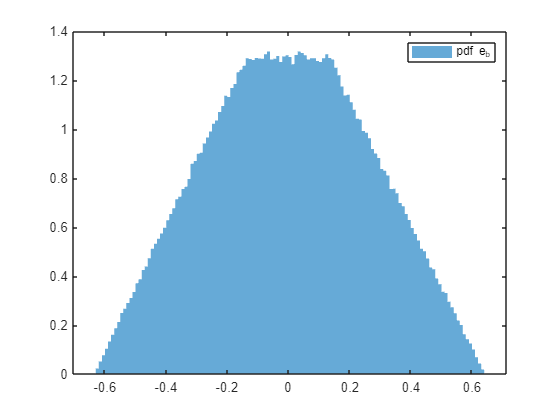

histogram(e_b,'Normalization','pdf','EdgeColor','none')
legend('pdf e_b')

U_b = max(abs(e_b))

U_b = 0.6409

u_b = std(e_b)

u_b = 0.2666

Ucp_b = quantile(e_b,(1+cp)/2)

Ucp_b = 0.5016

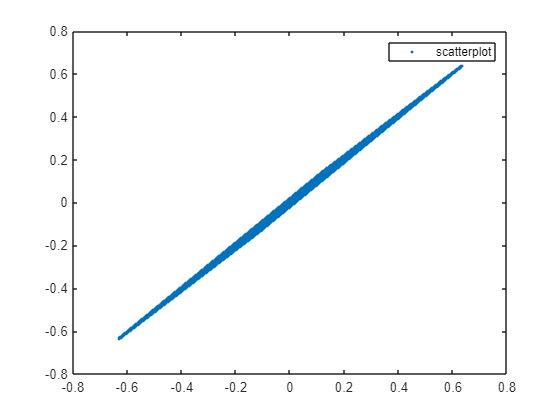

plot(e_h,e_b,'.')
legend('scatterplot')

R_theta_MC = corrcoef(e_h,e_b)

R_theta_MC =     1.0000    0.9995
    0.9995    1.0000


Calcolo manuale del coefficiente di correlazione a partire dai vettori e_h, e_b

e_h

e_h =    -0.2261   -0.0453    0.0731   -0.1344    0.3771   -0.2682   -0.2495   -0.1895    0.0422   -0.1860   -0.1180   -0.2415   -0.1693   -0.0865    0.0016    0.5241    0.1362    0.3556    0.2488    0.1169   -0.0725    0.0140    0.4453   -0.1357   -0.1788   -0.1276    0.3487    0.1566    0.2177   -0.2354   -0.1196   -0.0183    0.3576    0.2391    0.1119    0.1427    0.0159   -0.1439   -0.1423   -0.0117    0.2696   -0.3036   -0.1328   -0.4869   -0.0222    0.1612   -0.2900    0.2058    0.2471   -0.2651


e_b

e_b =    -0.2439   -0.0627    0.0606   -0.1282    0.3853   -0.2803   -0.2465   -0.1802    0.0363   -0.1949   -0.1211   -0.2355   -0.1763   -0.0819    0.0072    0.5275    0.1292    0.3662    0.2631    0.1052   -0.0738   -0.0027    0.4558   -0.1298   -0.1753   -0.1146    0.3524    0.1740    0.2090   -0.2468   -0.1370   -0.0049    0.3711    0.2519    0.1167    0.1379    0.0002   -0.1573   -0.1539   -0.0215    0.2763   -0.3113   -0.1208   -0.4910   -0.0181    0.1544   -0.2923    0.2163    0.2409   -0.2803


sigmaXY = mean(e_h.*e_b) % perché gli errori sono a media nulla

sigmaXY = 0.0701

sigmaX = sqrt(mean(e_h.^2))

sigmaX = 0.2632

sigmaX = std(e_h)

sigmaX = 0.2632

sigmaY = sqrt(mean(e_b.^2))

sigmaY = 0.2666

rhoXY = sigmaXY/(sigmaX*sigmaY)

rhoXY = 0.9995

## Misure mediante triangolazione (coefficienti di sensibilità relativi)

Grandezze in ingresso e in uscita:

- x = [a; gamma] % vettore grandezze in ingresso

- theta = [h; b] % vettore in uscita grandezze in uscita

Modello della misurazione:

- h = a*tan(gamma)

- b = a/cos(gamma)

### Calcolo simbolico della matrice Cr

clear
syms a gamma real
x = [a;gamma] % variabili di ingresso

h = a*tan(gamma); % altezza
b = a/cos(gamma); % distanza dalla sommità
theta = [h;b] % variabili di uscita

Cr = jacobian(log(theta),x).*x' % matrice jacobiana logaritmica

### Quesito

% Si calcolino le grandezze in uscita e le loro incertezze, in base ai dati sulle grandezze in ingresso. 
% Gli errori in
% ingresso sono indipendenti.
% Convenzione:
% x = [a; gamma] % vettore grandezze in ingresso
% theta = [h; b] % vettore in uscita grandezze in uscita

% Dati
clear
a = 10
gamma_deg = 75 % angolo in gradi
Ur_a = 0.01 % incertezza relativa
U_gamma_deg = 0.1 % incertezza assoluta in gradi
cp = 0.95

% Domande
% h
% b
% Ur % vettore WCU relative in ingresso
% ur % vettore SU relative in ingresso
% Cr % matrice coefficienti di sensibilità relativi
% Ur_theta % vettore WCU relative in uscita 
% ur_theta % vettore SU relative in uscita
% R_theta % matrice coefficienti di correlazione in uscita
% rho_theta_12 % coefficiente di correlazione tra gli errori in uscita sulle grandezze theta(1) e theta(2)
% kcp % fattore di copertura per la probabilità di copertura cp
% kmax % massimo fattore di copertura applicabile 
% Urcp_theta % vettore incertezze estese relative in uscita con probabilità di copertura cp

### Soluzione

gamma = gamma_deg/180*pi
h = a*tan(gamma)
b = a/cos(gamma)

U_gamma = U_gamma_deg/180*pi
Ur_gamma = U_gamma/abs(gamma)
Ur = [Ur_a; Ur_gamma]
ur = Ur/sqrt(3)
Sigmar = diag(ur)^2

Cr = [1, (gamma*(tan(gamma)^2 + 1))/tan(gamma); 1, (gamma*sin(gamma))/cos(gamma)]

Ur_theta = abs(Cr)*Ur

Sigmar_theta = Cr*Sigmar*Cr'

ur_theta = sqrt(diag(Sigmar_theta))

R_theta = diag(ur_theta)^-1*Sigmar_theta*diag(ur_theta)^-1

rho_theta_12 = R_theta(1,2)

kmax = Ur_theta./ur_theta
kcp = norminv((1+cp)/2)
Urcp_theta = kcp*ur_theta

## Calcolo di modulo e argomento (d,phi) di un numero complesso, date parte reale e immaginaria (a,b) - coefficienti di sensibilità assoluti

Il problema ricorre frequentemente lavorando con le sinusoidi. Se $p$ è il fasore di una sinusoide 

- 
$$x\left(t\right)=\textrm{Re}\left(p\;e^{j\omega \;t} \right)=d\;\cos \left(\omega \;t+\varphi \;\right)=a\;\cos \left(\omega \;t\right)-b\;\sin \left(\omega \;t\right)$$


allora:

- $a,b$ sono le componenti coseno e seno della sinusoide, ovvero le componenti "in fase" e "in quadratura"

- $d,\varphi \;$sono modulo e fase della sinusoide

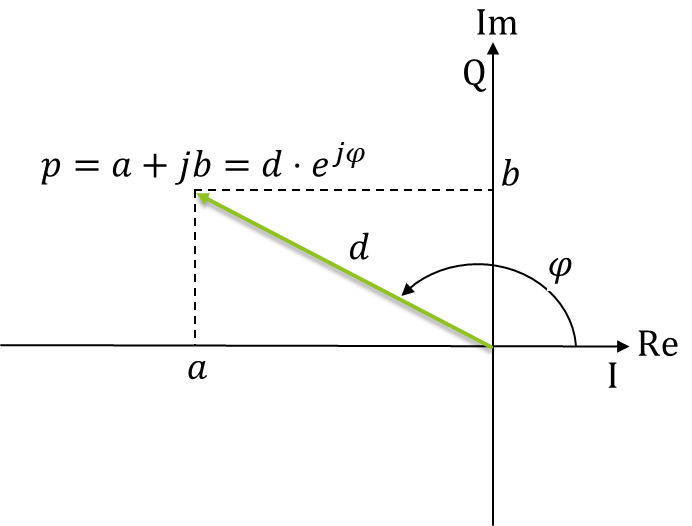

Grandezze in ingresso e in uscita:

- x = [a; b] % vettore grandezze in ingresso

- theta = [d; phi] % vettore in uscita grandezze in uscita

Modello della misurazione:

- d = sqrt(a^2+b^2)

- phi = atan2(b,a)

### Calcolo simbolico della matrice C

clear
syms a b real
x = [a; b]

d = sqrt(a^2+b^2)
phi = atan2(b,a)
theta = [d;phi]

C = simplify(jacobian(theta,x))

### Quesito

% Si calcolino le grandezze in uscita e le loro incertezze, in base ai dati sulle grandezze in ingresso. 
% Gli errori in ingresso sono indipendenti.

% Dati
clear
a = -10
b = -15
U_a = 0.01
U_b = 0.01
cp = 0.95

% Domande
% a
% phi
% U % vettore WCU in ingresso
% u % vettore SU in ingresso
% C % matrice coefficienti di sensibilità
% U_theta % vettore WCU in uscita 
% u_theta % vettore SU in uscita
% R_theta % matrice coefficienti di correlazione in uscita
% rho_theta_12 % coefficiente di correlazione tra gli errori in uscita sulle grandezze theta(1) e theta(2)
% kcp % fattore di copertura per la probabilità di copertura cp
% kmax % massimo fattore di copertura applicabile 
% Ucp_theta % vettore incertezze estese in uscita con probabilità di copertura cp

### Soluzione

d = sqrt(a^2+b^2)
phi = atan2(b,a)

U = [U_a; U_b]
u = U/sqrt(3)
Sigma = diag(u)^2

C = [a/d, b/d; -b/d^2, a/d^2]

U_theta = abs(C)*U

Sigma_theta = C*Sigma*C'

u_theta = sqrt(diag(Sigma_theta))

R_theta = diag(u_theta)^-1*Sigma_theta*diag(u_theta)^-1

rho_theta_12 = R_theta(1,2)

kmax = U_theta./u_theta
kcp = norminv((1+cp)/2)
Ucp_theta = kcp*u_theta

### Verifica con metodo Monte Carlo

Nsim = 1e6;
e_a = unifrnd(-U_a,U_a,[1,Nsim]);
e_b = unifrnd(-U_b,U_b,[1,Nsim]);
a_MC = a + e_a;
b_MC = b + e_b;

d_MC = sqrt(a_MC.^2+b_MC.^2);
phi_MC = atan2(b_MC,a_MC);

e_d = d_MC - d;
e_phi = phi_MC - phi;

histogram(e_d,'Normalization','pdf')
legend('pdf e_d')

U_d = max(abs(e_d))
u_d = std(e_d)
Ucp_d = quantile(e_d,(1+cp)/2)

histogram(e_phi,'Normalization','pdf')
legend('pdf e_\phi')

U_phi = max(abs(e_phi))
u_phi = std(e_phi)
Ucp_phi = quantile(e_phi,(1+cp)/2)

plot(e_d,e_phi)
legend('scatterplot')

R_MC = corrcoef(e_d,e_phi)


## Calcolo di parte reale e immaginaria (a,b) di un numero complesso, dati modulo e argomento (d,phi) - coefficienti di sensibilità assoluti

Grandezze in ingresso e in uscita:

- x = [d; phi] % vettore grandezze in ingresso

- theta = [a; b] % vettore in uscita grandezze in uscita

Modello della misurazione:

- a = d*cos(phi)

- b = d*sin(phi)

### Calcolo simbolico della matrice C

clear
syms d phi real
x = [d; phi]

a = d*cos(phi)
b = d*sin(phi)

theta = [a;b]

C = simplify(jacobian(theta,x))

### Quesito

% Si calcolino le grandezze in uscita e le loro incertezze, in base ai dati sulle grandezze in ingresso. 
% Gli errori in ingresso sono indipendenti.

% Dati
clear
d = 10
phi_deg = 165
Ur_d = 0.01 % incertezza relativa
Ur_phi = 0.01 % incertezza relativa
cp = 0.95

% Domande
% a
% b
% U % vettore WCU in ingresso
% u % vettore SU in ingresso
% C % matrice coefficienti di sensibilità
% U_theta % vettore WCU in uscita 
% u_theta % vettore SU in uscita
% R_theta % matrice coefficienti di correlazione in uscita
% rho_theta_12 % coefficiente di correlazione tra gli errori in uscita sulle grandezze theta(1) e theta(2)
% kcp % fattore di copertura per la probabilità di copertura cp
% kmax % massimo fattore di copertura applicabile 
% Ucp_theta % vettore incertezze estese in uscita con probabilità di copertura cp

### Soluzione

phi = phi_deg/180*pi
a = d*cos(phi)
b = d*sin(phi)

U_d = Ur_d*abs(d)
U_phi = Ur_phi*abs(phi)
U = [U_d; U_phi]
u = U/sqrt(3)
Sigma = diag(u)^2

C = [cos(phi), -d*sin(phi); sin(phi), d*cos(phi)]

U_theta = abs(C)*U

Sigma_theta = C*Sigma*C'

u_theta = sqrt(diag(Sigma_theta))

R_theta = diag(u_theta)^-1*Sigma_theta*diag(u_theta)^-1

rho_theta_12 = R_theta(1,2)

kmax = U_theta./u_theta
kcp = norminv((1+cp)/2)
Ucp_theta = kcp*u_theta

### Verifica con metodo Monte Carlo

Nsim = 1e6;
e_d = unifrnd(-U_d,U_d,[1,Nsim]);
e_phi = unifrnd(-U_phi,U_phi,[1,Nsim]);
d_MC = d + e_d;
phi_MC = phi + e_phi;

a_MC = d_MC.*cos(phi_MC);
b_MC = d_MC.*sin(phi_MC);

e_a = a_MC - a;
e_b = b_MC - b;

histogram(e_a,'Normalization','pdf')
legend('pdf e_a')

U_a = max(abs(e_a))
u_a = std(e_a)
Ucp_a = quantile(e_a,(1+cp)/2)

histogram(e_b,'Normalization','pdf')
legend('pdf e_b')

U_b = max(abs(e_b))
u_b = std(e_b)
Ucp_b = quantile(e_b,(1+cp)/2)

plot(e_a,e_b)
legend('scatterplot')

R_MC = corrcoef(e_a,e_b)

## Misura del raggio terrestre col metodo di Eratostene (coefficienti di sensibilità relativi)

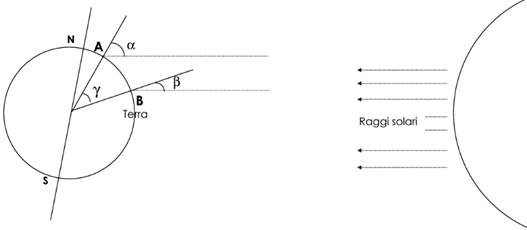 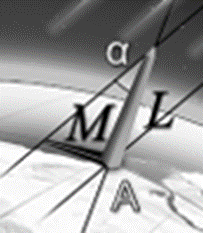

Le relazioni che danno il raggio terrestre sono le seguenti:

$\alpha =\textrm{atan}{\left(\frac{M_a }{L_a }\right)}$ angolo di incidenza dei raggi solari nella città A

$\beta =\textrm{atan}{\left(\frac{M_b }{L_b }\right)}$ angolo di incidenza dei raggi solari nella città B

$\gamma =\ \alpha -\beta$ angolo tra la città A e la città B

$C=D\frac{2\pi }{\gamma }$ circonferenza terrestre ($D$ = distanza tra le città A e B)

$R=\frac{C}{2\pi \;}$ raggio terrestre

In definitiva:


$$R=\frac{D}{\textrm{atan}{\left(\frac{M_a }{L_a }\right)}-\textrm{atan}{\left(\frac{M_b }{L_b }\right)}}$$


### Calcolo simbolico della matrice Cr

clear
syms D Ma La Mb Lb real positive
x = [D; Ma; La; Mb; Lb] % variabili di ingresso, nell'ordine scelto

alpha = atan(Ma/La);
beta = atan(Mb/Lb);
gamma = alpha - beta;
C = D*2*pi/gamma;
R = C/(2*pi);

theta = R % variabili di uscita, nell'ordine scelto

C_r = simplify(jacobian(log(theta),x).*x')

### Quesito (le derivate sono un po' troppo complesse per essere richieste all'esame)

All'esame non ci saranno problemi con derivate così complesse: lo scopo del corso e dell'esame è un'altro

% Si calcolino le grandezze in uscita e le loro incertezze, in base ai dati sulle grandezze in ingresso. 
% Gli errori in ingresso sono indipendenti.

% Dati
clear
D = 389 % distanza Enna - Caserta (km)
La = 1 % lunghezza gnomone Enna (m)
Ma = 1.658 % lunghezza ombra Enna (m)
Lb = 1 % lunghezza gnomone Caserta (m)
Mb = 1.45 % lunghezza ombra Caserta (m)

Ur_D = 0.01 % incertezza relative di D
Ur0 = 0.001 % incertezza relativa delle altre misure in ingresso

cp = 0.95

% Domande
% R % misura in uscita
% Ur % vettore WCU in ingresso relative
% ur % vettore SU in ingresso relative
% Cr % matrice coefficienti di sensibilità relativi
% Ur_theta % vettore WCU in uscita relative
% ur_theta % vettore SU in uscita relative
% kcp % fattore di copertura per la probabilità di copertura cp
% kmax % massimo fattore di copertura applicabile 
% Urcp_theta % vettore incertezze estese relative in uscita con probabilità di copertura cp

### Soluzione

alpha = atan(Ma/La);
beta = atan(Mb/Lb);
gamma = alpha - beta;
C = D*2*pi/gamma;
R = C/(2*pi)

Ur = [Ur_D; Ur0; Ur0; Ur0; Ur0] % 5 misure in ingresso
ur = Ur/sqrt(3)

% Scriviamo Cr presupponendo x = [D; Ma; La; Mb; Lb]
s1 = (Lb*Mb)/((atan(La/Ma) - atan(Lb/Mb))*(Lb^2 + Mb^2));
s2 = (La*Ma)/((atan(La/Ma) - atan(Lb/Mb))*(La^2 + Ma^2));
Cr = [1, s2, -s2, -s1, s1]

% Copia e incolla da Matlab
Cr = [1, (La*Ma)/((atan(La/Ma) - atan(Lb/Mb))*(La^2 + Ma^2)), -(La*Ma)/((atan(La/Ma) - atan(Lb/Mb))*(La^2 + Ma^2)), -(Lb*Mb)/((atan(La/Ma) - atan(Lb/Mb))*(Lb^2 + Mb^2)), (Lb*Mb)/((atan(La/Ma) - atan(Lb/Mb))*(Lb^2 + Mb^2))]

Ur_theta = abs(Cr)*Ur

% SU: metodo semplice, per errori di ingresso incorrelati e una sola variabile di uscita
ur_theta = sqrt(Cr.^2*ur.^2) 

% SU: metodo generale
Sigmar = diag(ur)^2;
Sigmar_theta = Cr*Sigmar*Cr';
ur_theta = sqrt(diag(Sigmar_theta))

kmax = Ur_theta./ur_theta
kcp = norminv((1+cp)/2)
Urcp_theta = kcp*ur_theta

### Verifica con metodo Monte Carlo

Nsim = 1e6;
er_D = unifrnd(-Ur_D,Ur_D,[1,Nsim]);
er_Ma = unifrnd(-Ur0,Ur0,[1,Nsim]);
er_La = unifrnd(-Ur0,Ur0,[1,Nsim]);
er_Mb = unifrnd(-Ur0,Ur0,[1,Nsim]);
er_Lb = unifrnd(-Ur0,Ur0,[1,Nsim]);

D_MC = D*(1 + er_D); % o anche D + er_D*D
Ma_MC = Ma*(1 + er_Ma);
La_MC = La*(1 + er_La);
Mb_MC = Mb*(1 + er_Mb);
Lb_MC = Lb*(1 + er_Lb);

alpha_MC = atan(Ma_MC./La_MC);
beta_MC = atan(Mb_MC./Lb_MC);
gamma_MC = alpha_MC - beta_MC;
C_MC = D_MC*2*pi./gamma_MC;
R_MC = C_MC/(2*pi)

er_R = (R_MC - R)/R

histogram(er_R,'Normalization','pdf','EdgeColor','none')
legend('pdf e_{r,R}')

br_R = mean(er_R)

Ur_R = max(abs(er_R))
ur_R = std(er_R)
Urcp_R = quantile(er_R,(1+cp)/2)

## Misura di capacità mediante risposta al gradino di circuito RC

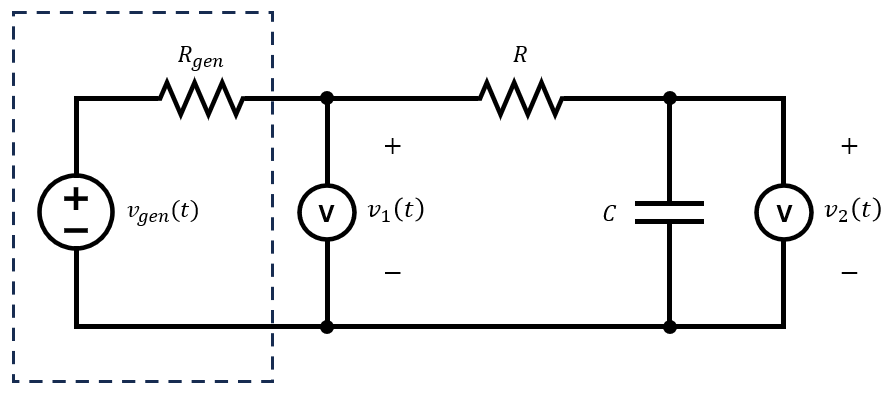

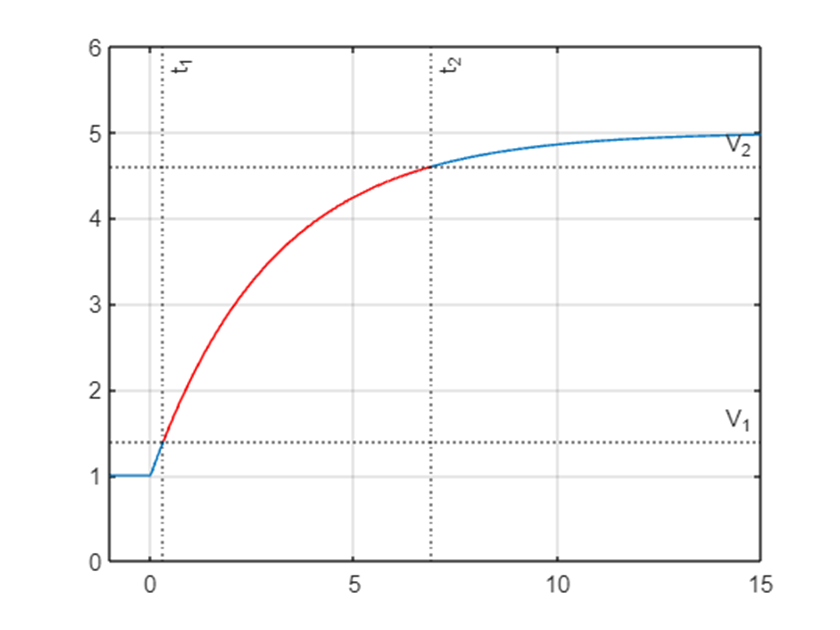

Sappiamo che:


$$t_r =\tau \;\;\log \left(9\right)$$



$$C_{tr} =\frac{t_r }{{\left(R+R_{gen} \right)}\cdot \log \left(9\right)\;}$$


### Calcolo simbolico della matrice Cr

clear
syms t_r R R_gen real
x = [t_r; R; R_gen]

C_tr = t_r/((R+R_gen)*log(sym(9))) % se si scrive log(9) si ottengono risultati "brutti"

theta = C_tr;

C = simplify(jacobian(theta,x)) % coefficienti sensibilità assoluti
C_r = simplify(jacobian(log(theta),x).*x') % coefficienti sensibilità assoluti

### Quesito

% Si calcolino le grandezze in uscita e le loro incertezze, in base ai dati sulle grandezze in ingresso. 
% Gli errori in ingresso sono indipendenti.

% Dati
clear
Rgen = 50
R = 100
tr = 155e-9 % ns

Ur0 = 0.01 % incertezza relativa su tutte le misure

cp = 0.95

% Domande
% Ctr % misura in uscita
% Ur % vettore WCU in ingresso relative
% ur % vettore SU in ingresso relative
% Cr % matrice coefficienti di sensibilità relativi
% Ur_theta % vettore WCU in uscita relative
% ur_theta % vettore SU in uscita relative
% kcp % fattore di copertura per la probabilità di copertura cp
% kmax % massimo fattore di copertura applicabile 
% Urcp_theta % vettore incertezze estese relative in uscita con probabilità di copertura cp

### Soluzione

Ctr = tr/((R+Rgen)*log(9))

Ur = [Ur0; Ur0; Ur0] % 3 misure in ingresso
Ur = Ur0*ones(3,1)
ur = Ur/sqrt(3)

% Scriviamo Cr presupponendo x = [tr; R; Rgen]
Cr = [1, -R/(R + Rgen), -Rgen/(R + Rgen)]

Ur_theta = abs(Cr)*Ur

% SU: metodo semplice, per errori di ingresso incorrelati e una sola variabile di uscita
ur_theta = sqrt(Cr.^2*ur.^2) 

% SU: metodo generale
Sigmar = diag(ur)^2;
Sigmar_theta = Cr*Sigmar*Cr';
ur_theta = sqrt(diag(Sigmar_theta))

kmax = Ur_theta./ur_theta
kcp = norminv((1+cp)/2)
Urcp_theta = kcp*ur_theta

### Verifica con metodo Monte Carlo

Nsim = 1e6;
er_tr = unifrnd(-Ur0,Ur0,[1,Nsim]);
er_R = unifrnd(-Ur0,Ur0,[1,Nsim]);
er_Rgen = unifrnd(-Ur0,Ur0,[1,Nsim]);

tr_MC = tr*(1 + er_tr); % o anche tr + er_tr*tr
R_MC = R*(1 + er_R);
Rgen_MC = Rgen*(1 + er_Rgen);

C_MC = tr_MC./((R_MC+Rgen_MC)*log(9));

er_C = (C_MC - Ctr)/Ctr

histogram(er_C,'Normalization','pdf','EdgeColor','none')
legend('pdf e_{r,C}')

br_tr = mean(er_C)

Ur_tr = max(abs(er_C))
ur_tr = std(er_C)
Urcp_tr = quantile(er_C,(1+cp)/2)

## Misura di capacità mediante risposta di ampiezza single-tone di circuito RC

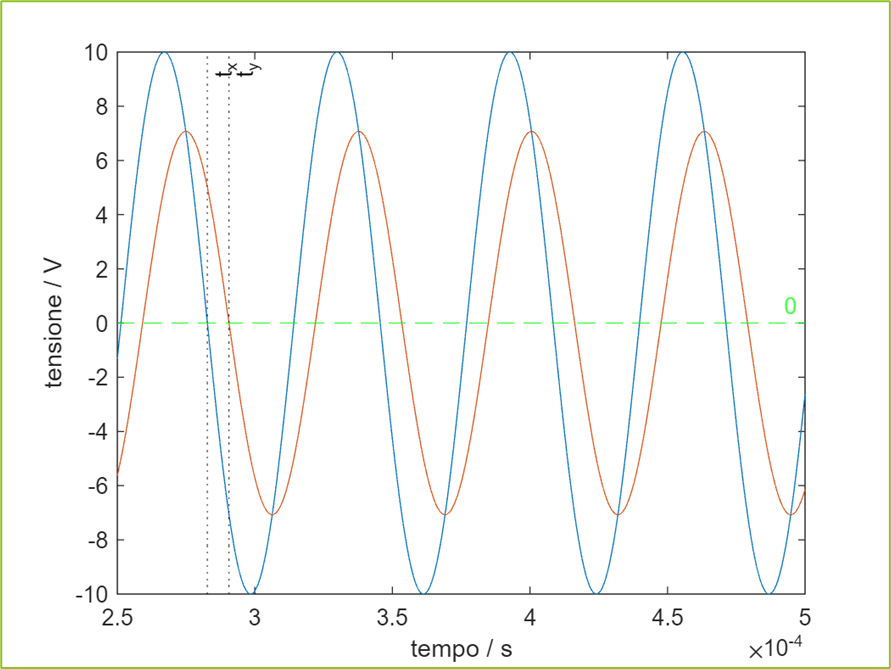

Sappiamo che:


$$H=\frac{V_{\textrm{pp},\textrm{out}} }{V_{\textrm{pp},\textrm{in}} }$$



$$H=\frac{1}{\sqrt{1+{\left(\frac{f}{f_c }\right)}^2 \;}}$$



$$f_{c\;} =\frac{1}{2\pi \;\tau \;}=\frac{1}{2\pi \;R\;C}$$



$$C_H =\frac{\sqrt{1-H^2 \;}}{H}\;\frac{1}{2\pi \;R\;f}$$


### Calcolo simbolico della matrice Cr

clear
syms H f R real
x = [H; f; R]

C_H = 1/(2*pi*R*f)*sqrt(1-H^2)/H % misura di capacità da risposta di ampiezza single-tone
theta = C_H;

C = simplify(jacobian(theta,x)) % coefficienti sensibilità assoluti
C_r = simplify(jacobian(log(theta),x).*x')

### Quesito

% Si calcolino le grandezze in uscita e le loro incertezze, in base ai dati sulle grandezze in ingresso. 
% Gli errori in ingresso sono indipendenti.

% Dati
clear
Rgen = 50
R = 100
f = 100e3
H = 0.32

Ur0 = 0.01 % incertezza relativa su tutte le misure

cp = 0.95

% Domande
% Ctr % misura in uscita
% Ur % vettore WCU in ingresso relative
% ur % vettore SU in ingresso relative
% Cr % matrice coefficienti di sensibilità relativi
% Ur_theta % vettore WCU in uscita relative
% ur_theta % vettore SU in uscita relative
% kcp % fattore di copertura per la probabilità di copertura cp
% kmax % massimo fattore di copertura applicabile 
% Urcp_theta % vettore incertezze estese relative in uscita con probabilità di copertura cp

### Soluzione

CH = 1/(2*pi*R*f)*sqrt(1-H^2)/H

Ur = [Ur0; Ur0; Ur0] % 3 misure in ingresso
Ur = Ur0*ones(3,1)
ur = Ur/sqrt(3)

% Scriviamo Cr presupponendo x = [H; f; R]
Cr = [1/(H^2 - 1), -1, -1]

Ur_theta = abs(Cr)*Ur

% SU: metodo semplice, per errori di ingresso incorrelati e una sola variabile di uscita
ur_theta = sqrt(Cr.^2*ur.^2) 

% SU: metodo generale
Sigmar = diag(ur)^2;
Sigmar_theta = Cr*Sigmar*Cr';
ur_theta = sqrt(diag(Sigmar_theta))

kmax = Ur_theta./ur_theta
kcp = norminv((1+cp)/2)
Urcp_theta = kcp*ur_theta

### Verifica con metodo Monte Carlo

Nsim = 1e6;
er_H = unifrnd(-Ur0,Ur0,[1,Nsim]);
er_f = unifrnd(-Ur0,Ur0,[1,Nsim]);
er_R = unifrnd(-Ur0,Ur0,[1,Nsim]);

H_MC = H*(1 + er_H); % o anche tr + er_tr*tr
f_MC = f*(1 + er_f);
R_MC = R*(1 + er_R);

C_MC = 1./(2*pi*R_MC.*f_MC).*sqrt(1-H_MC.^2)./H_MC;

er_C = (C_MC - CH)/CH

histogram(er_C,'Normalization','pdf','EdgeColor','none')
legend('pdf e_{r,C}')

br_C = mean(er_C)

Ur_C = max(abs(er_C))
ur_C = std(er_C)
Urcp_C = quantile(er_C,(1+cp)/2)